# RANDWALK 

## Perform a random walk on a square grid

Starts at (0,0) and walks randomly on a square grid until one of the boundaries (x or y = +/- 10) is reached.  All directions are equally likely during the walk, and there is no path memory (other than for visualization).

## Initialization

x = 0;
y = 0;
xv = x;
yv = y;

## Perform walk

Walk until x OR y = +/- 10

while (abs(x)<10) && (abs(y)<10)
    
    % Roll dice and move
    dice = randi(4);
    % Choose direction for move, based on dice roll
    switch dice
        case 1      % 1 = N
            y=y+1;
        case 2      % 2 = E
            x=x+1;
        case 3      % 3 = S
            y=y-1;
        otherwise   % 4 = W
            x=x-1;
    end
    xv(end+1) = x;  %#ok
    yv(end+1) = y;  %#ok
    
end
%  Reached a boundary, so we're done.

## Plot result

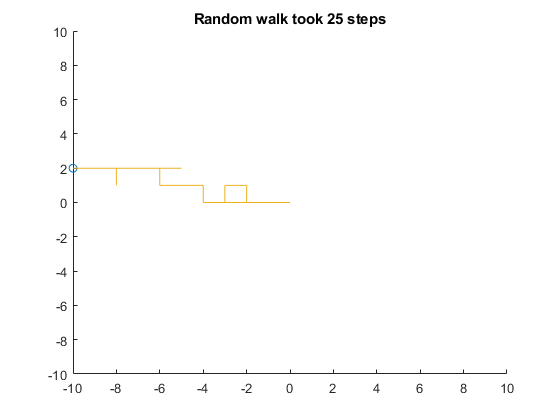

axis([-10,10,-10,10])
title("Random walk took " + length(xv) + " steps")
hold on
comet(xv,yv)
hold off